clear all;
close all;


## `Exercice 1`

`La hauteur d’eau h(m) est mesurée à l’aide  d’un capteur (-10 +10V) de constante de  temps négligeable. Le débit d’entrée qe(m3/s)  est déterminé à partir de la tension (-10 +10V)  appliquée à la pompe de constante de temps  négligeable. La hauteur minimum est de 0 m,  la hauteur maximum est de 0,6 m. Le débit  d’entrée minimum est de 0 m3/s, le débit  maximum est de 1,1 10-4 m3/s.`

`En supposant que l'équation dynamique (donc structure du modèle connu) qui régit le système  peut s'écrire sous la forme autour d’un point de fonctionnement :  h(k+1)= a h(k) + b qe(k)`

### `Partie A `

#### `1/ Estimer les paramètres â et b̂ du modèle décrit par (1) à partir des données k établies à la période  d'échantillonnage Te=1s autour de ce même point de fonctionnement sans bruit de mesure issue  du capteur (campagne cuve1.mat) puis avec bruit de mesure issue du capteur (campagne  cuve2.mat).  `

#### `Les paramètres pourront être estimés selon la méthode des moindres carrés à l’aide de 50% de  données pour l’estimation, le reste des données servant à l’étape de validation au travers un modèle de prédiction décrit par : ĥ(k+1)= â h(k) + b̂ qe(k)`

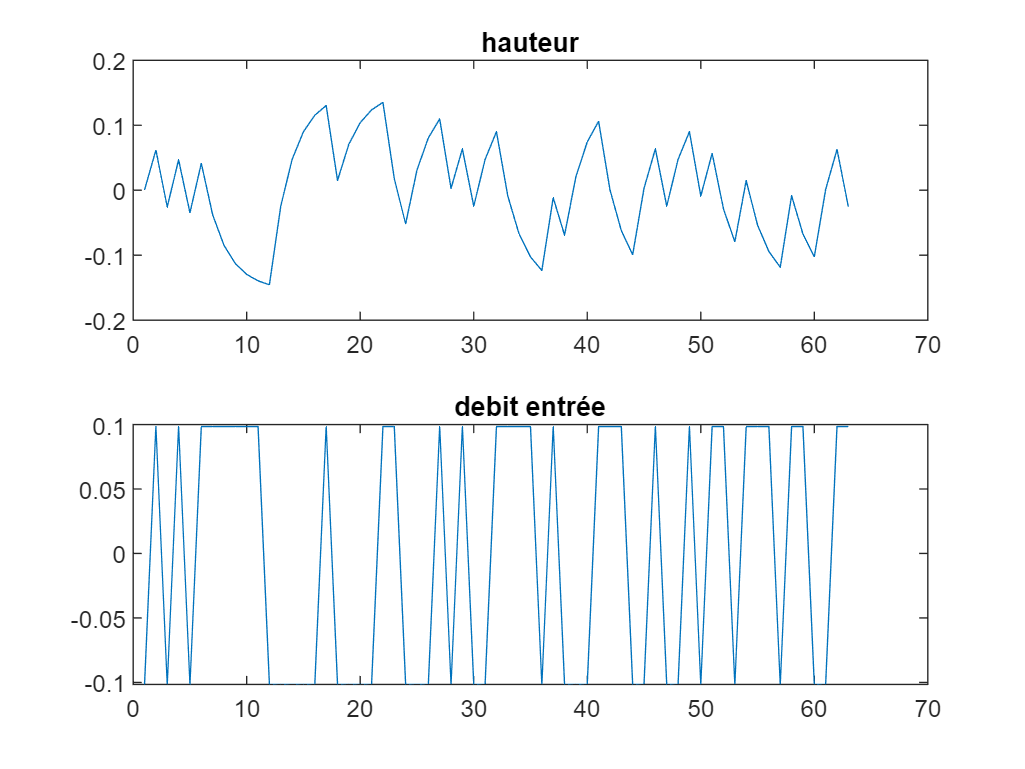

load cuve1.mat
load cuve2.mat
load cuve3.mat
load cuve4.mat

figure(1);
subplot(2,1,1);
plot(h1);
title("hauteur");
subplot(2,1,2);
plot(qe1);
title("debit entrée")

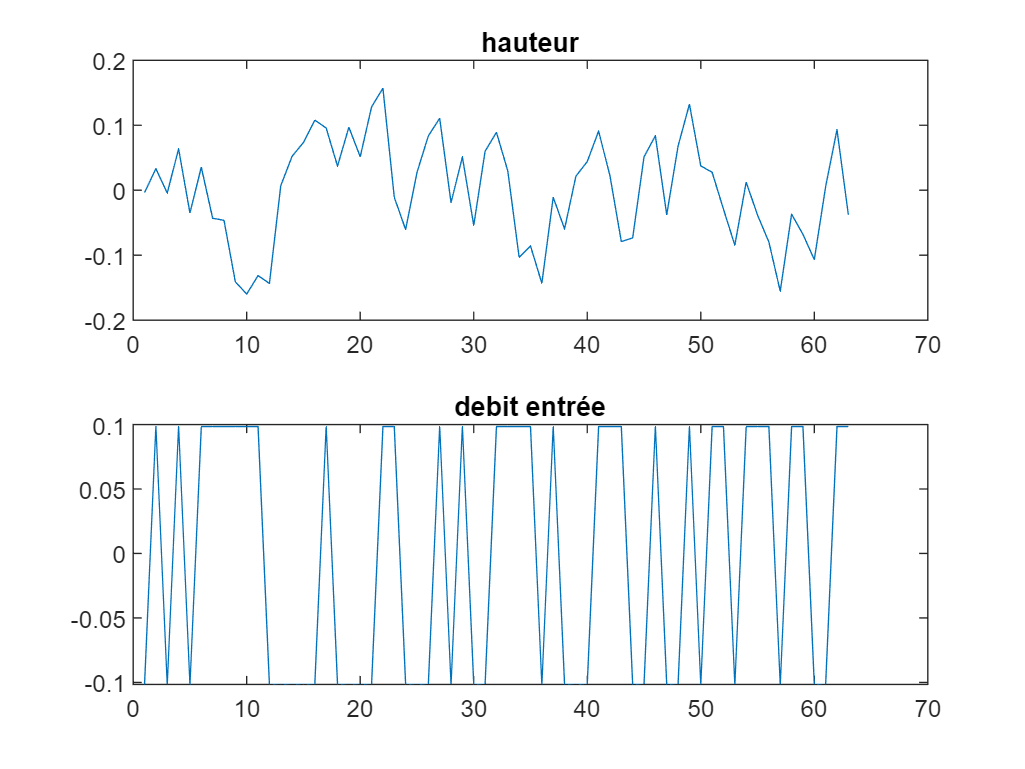


figure(2)
subplot(2,1,1);
plot(h2);
title("hauteur");
subplot(2,1,2);
plot(qe2);
title("debit entrée")

On a chargé et tracé les données de cuve1.mat et cuve2.mat

On remarque bien que les données de cuve1 sont sans bruits.

Y1 = h1(2:63);
X1 = [h1(1:62) qe1(1:62)];

[B, Bint] = regress(Y1, X1);

Y1est = X1*B;


On identifie les données de notre problème avec l'equation de depart des moindres carés : Y = X*B

Puis on utilise la fonction regress afin de determiner les paramètres a et b.

`2/ Comparer vos résultats vis-à-vis de â et b̂ ainsi que l’erreur de prédiction h(k+1)-ĥ(k+1) suivant  un classique critère quadratique pour les deux campagnes. `

Y2 = h2(2:63);
X2 = [h2(1:62) qe2(1:62)];
Y2est = X2 * B;

On determine ensuite grace à nos paramètres y2 estimé

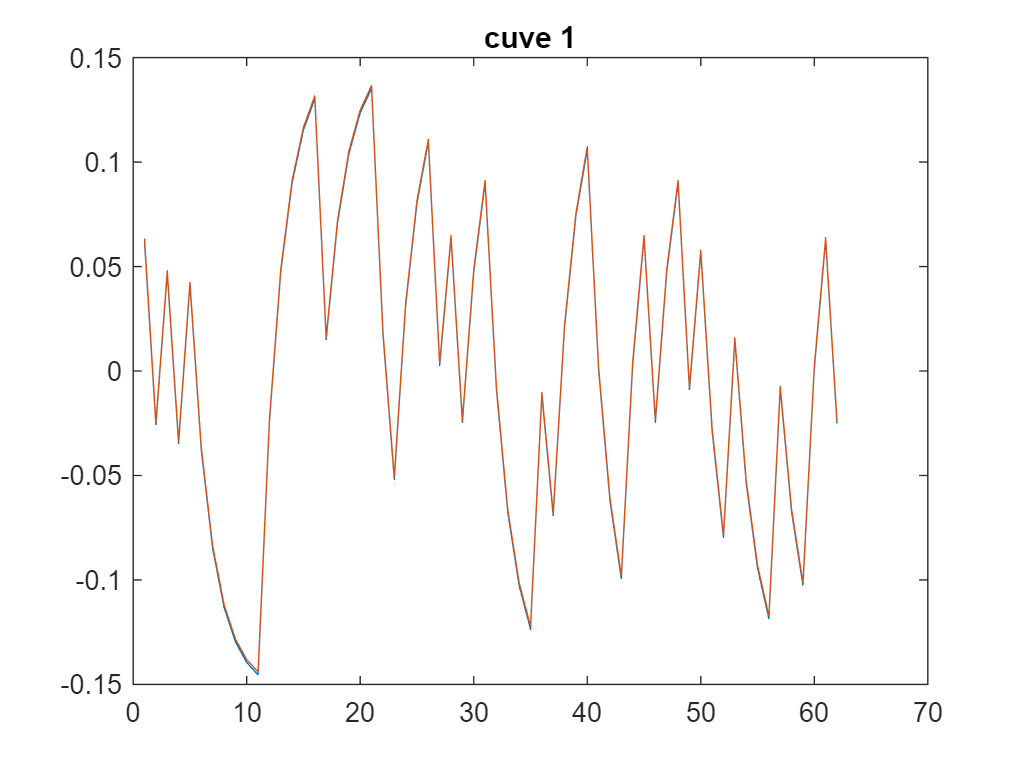

figure(3);
plot([Y1, Y1est]);
title("cuve 1");

On trace sur un même graph Y2 réél et Y2 estimé. Les courbes sont superposées : c'est normal, on a estimé les paramètres sur ces données

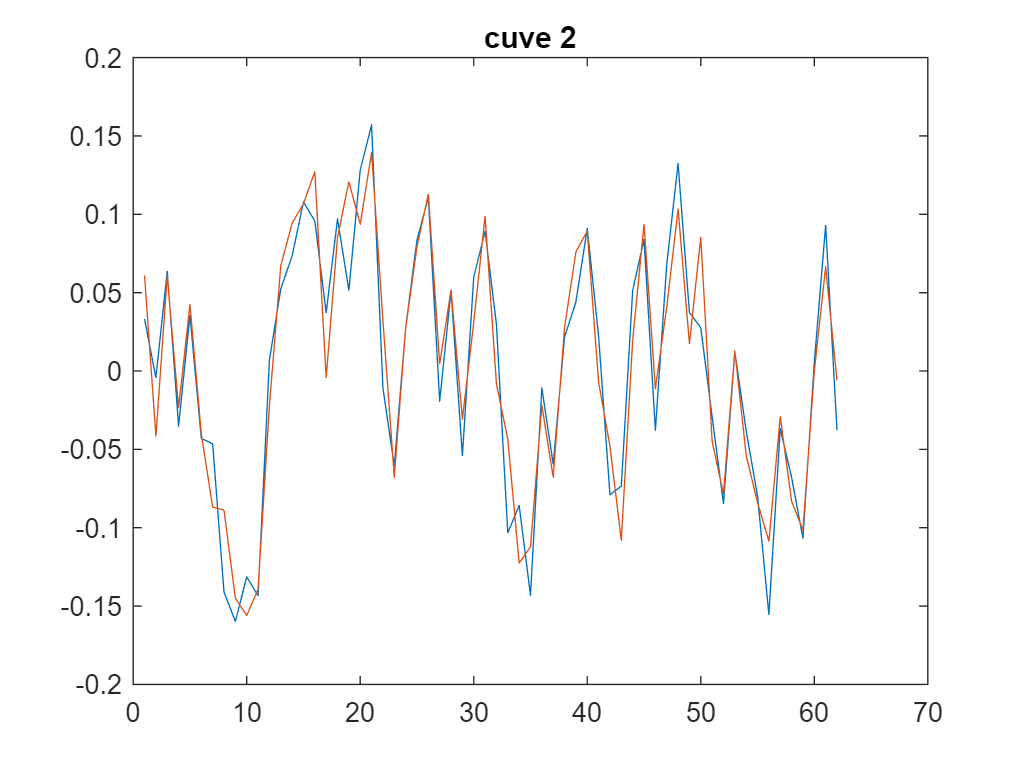

figure(4);
plot([Y2, Y2est]);
title("cuve 2");

Pour la cuve 2, les courbes de sont pas superposée. En effet, ce sont nos données de validation et pas d'estimation.

`Nous avons également réalisé deux campagnes de mesures (cuve3.mat et cuve4.mat) autour du  même point de fonctionnement relevées à la période d'échantillonnage Te=1s.  `

`3/ A partir de l’un des modèles établis, que pouvez-vous en déduire sur les campagnes  enregistrées ?`

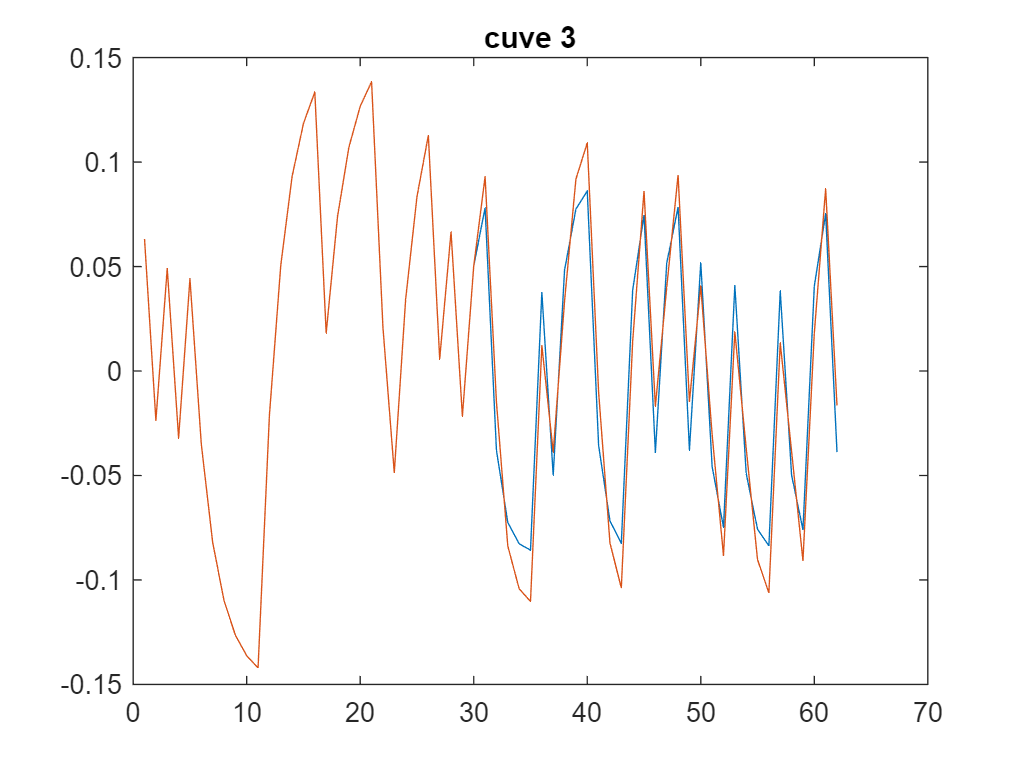

Y3 = h3(2:63);
X3 = [h3(1:62) qe3(1:62)];
Y3est = X3 * B;
figure(4);
plot([Y3, Y3est]);
title("cuve 3")

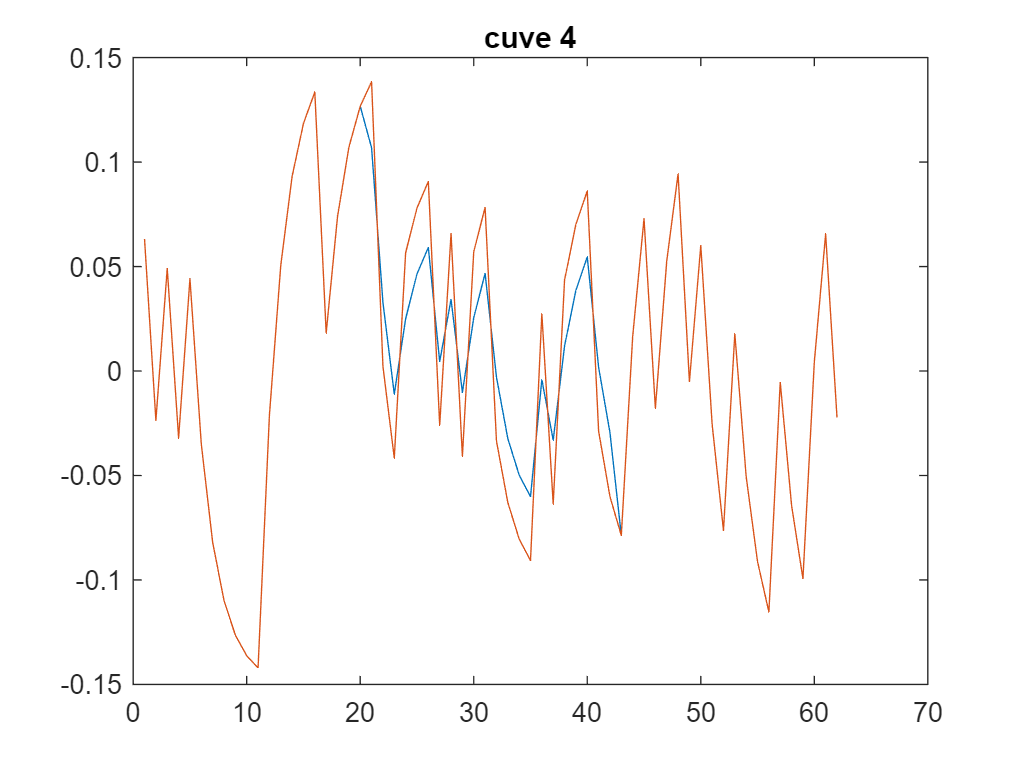


Y4 = h4(2:63);
X4 = [h4(1:62) qe4(1:62)];
Y4est = X4 * B;
figure(5);
plot([Y4, Y4est]);
title("cuve 4")

On refait la même chose sur les données des cuves 3 et 4. 

On observes que les données de ces cuves ne sont pas saines.

### Partie B

`4/ Etablir un modèle de prédiction à partir d’une approche basée par Réseaux de Neurones en  s’attachant à considérer comme entrée h(k) et qe(k) en comme sortie désirée h(k+1). Vous choisirez un NN à une couche cachée composée de n neurones avec des fonctions  d’activation de type tangente hyperbolique (variant entre -1 et +1) en sortie également.  `

`L’algorithme d’optimisation sera choisi parmi ceux proposé. Dans un premier temps, tester  l’algorithme ci-dessous en indiquant ce que vaut n. `

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.08 |         0.07 |       0.0033 |       0.0026 |          0.0100 |
|      50 |          50 |       00:00:08 |         0.08 |              |       0.0029 |              |          0.0100 |
|     100 |         100 |       00:00:09 |         0.08 |         0.08 |       0.0029 |       0.0033 |          0.0100 |
|     150 |         150 |       00:00:10 |         0.07 |              |       0.0027 |              |          0.0100 |
|     20

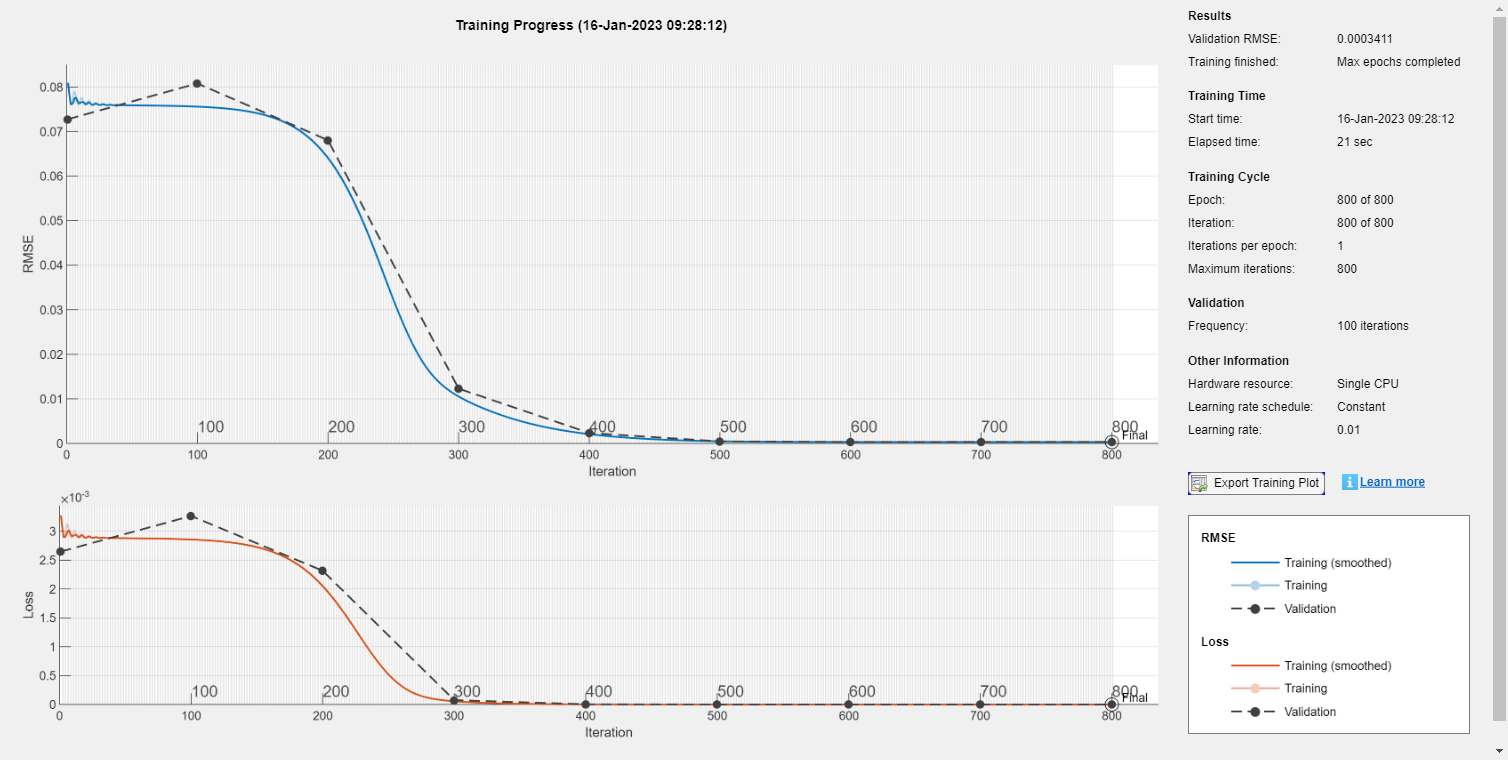

clear all;echo off;close all
load cuve1.mat % Données sans bruit
%%%% NNN
X = [h1(1:62) qe1(1:62)]';
Y = h1(2:63)';
% Initialize params for trainTestSplit
trainingSize = 0.5;
% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xval, Yval] = trainTestSplit(X', Y', trainingSize);
Xtrain=Xtrain';Ytrain=Ytrain';Xval=Xval'; Yval=Yval';
% Specify neural network architecture
layers = [... 
 sequenceInputLayer(size(Xtrain, 1)), ... % Input data layer
 fullyConnectedLayer(1, ... % Hidden layer 1 with 1 nodes
 'WeightsInitializer', 'narrow-normal', ...
 'BiasInitializer', 'narrow-normal'), ...
 tanhLayer, ... % Activation function 1
 fullyConnectedLayer(1, ... % Output layer with 1 node
 'WeightsInitializer', 'narrow-normal', ...
 'BiasInitializer', 'narrow-normal'), ...
 tanhLayer, ... % % Activation function 2
 regressionLayer ... % Label encode
];
% Spcify hyperparameters for neural network
% 'sgdm' - Stochastic gradient descent with momentum.
% 'adam' - Adaptive moment estimation (ADAM)
% 'rmsprop' - Root mean square propagation (RMSProp).
options = trainingOptions(...
 'sgdm', ... % sgdm optimization
 'InitialLearnRate', 0.01, ... % Set the initial learning rate to 0.01 
 'MaxEpochs', 800, ... % Maximum number of epochs to train algorithm
 'ValidationData', {Xval, Yval}, ... % Dataset to use as the validation set
 'ValidationFrequency', 100, ... % Frequency to validate the network at regular intervals
 'Verbose', true, ... % Outputs information about training 
 'Shuffle', 'every-epoch', ... % Data shuffling for every epoch
 'Plots', 'training-progress' ... % Show plots for every epoch
); 
% Function to visualize the layers object
analyzeNetwork(layers)
[dnn, trainingInfo] = trainNetwork(Xtrain, Ytrain, layers, options);

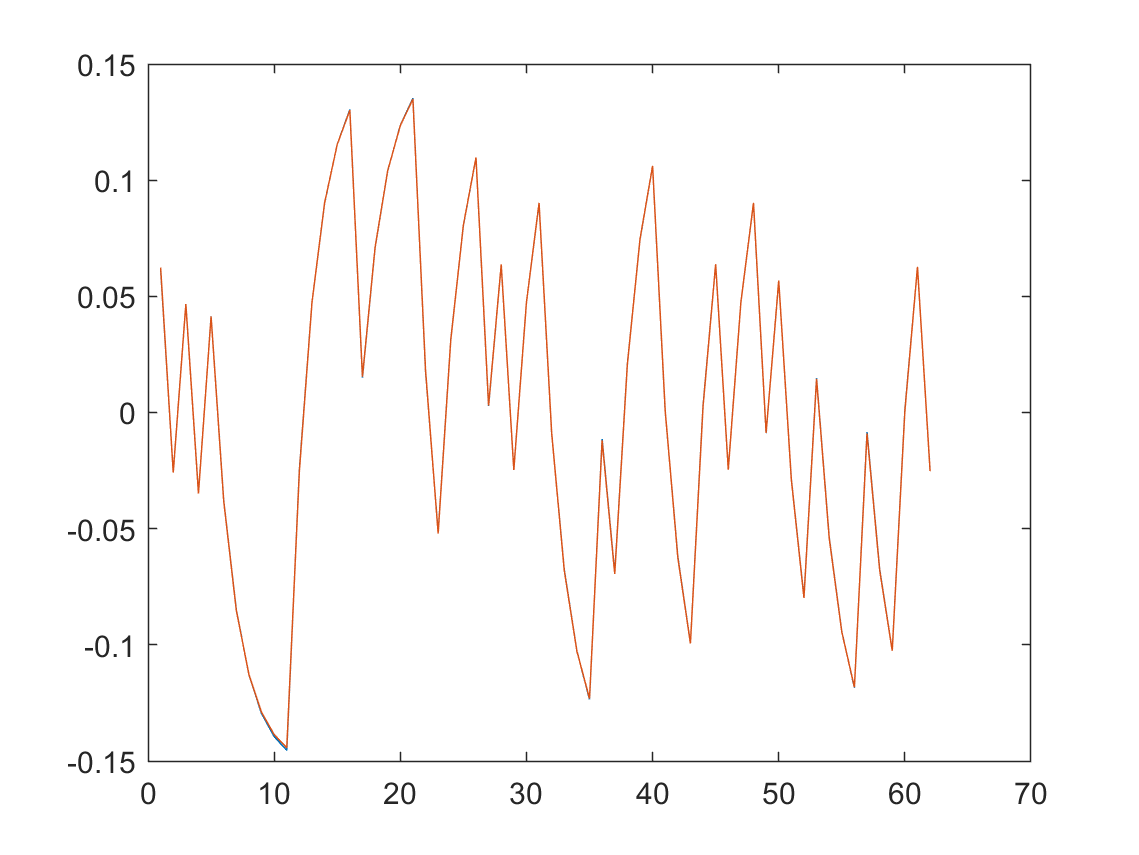

% Perform classification with DNN
ypred_dnn = predict(dnn,X);
figure(1);plot([Y' ypred_dnn'])

n = 

`5/ Indiquer les performances (*) du NN vis-à-vis du nombre de neurones (n=1 à 30) dans la couche  cachée. `

`* les performances pourront être considérées au regard d’un critère quadratique aux questions  précédentes cf 2).`

`6/ Indiquer, pour un nombre de neurones, les performances (*) du NN vis-à-vis du nombre  d’époques maximum de training considéré (par pas de 100 100 jusqu’à 1000). `

`7/ Indiquer, pour un nombre de neurones, les performances (*) du NN vis-à-vis du nombre de  données considérées pour le training (0.1 à 0.9) pour chaque campagne. `

function [Xtrain, Ytrain, Xval, Yval] = trainTestSplit(X, Y, trainingSize)
   % INPUTS
   % X: A numeric array of n observations by p predictor variables.
   % Y: A non-cell array of n observations by t target variables.
   % trainingSize:   A floating value ranging from [0, 1] denoting the training size ratio.

   % OUTPUTS
   % Xtrain: An array that contains p predictors and n * trainingSize observations for training the model.
   % Xval:   An array that contains p predictors and n * (1 - trainingSize) observations for testing the model.
   % Ytrain: An array containing n * trainingSize observations for training the model.
   % Yval:   An array containing n * (1 - trainingSize) observations for testing the model.

    
    % Shuffle the dataset using the cvpartition function
    cvObj = cvpartition(size(X, 1), 'HoldOut', trainingSize);
    idx = cvObj.test;
    
    % Split into training and test data based on training size specified
    Xval  = X(~idx, :); Xtrain = X(idx,  :);
    Yval  = Y(~idx, :); Ytrain = Y(idx,  :);
end